# **LIÇÃO 1 - ANÁLISE MATRICIAL DE ESTRUTURAS**

### **Aluno: Leonardo Silveira Leite - RA: 291646**

#### **EXERCÍCIO II - Método Direto**

(1) Ache a solução analítica do problema da barra de seção constante com carga P(x) = p0 constante, considerando u(0) = ua = 0 e u(L) = ub, sendo um valor conhecido constante. Compare a sua solução com a obtida no código 1.8. A barra é feita de aço, a seção é circular com diâmetro 30 mm, e a carga constante de 1kN/m. Verifique sua resposta para diferentes valores de ub.

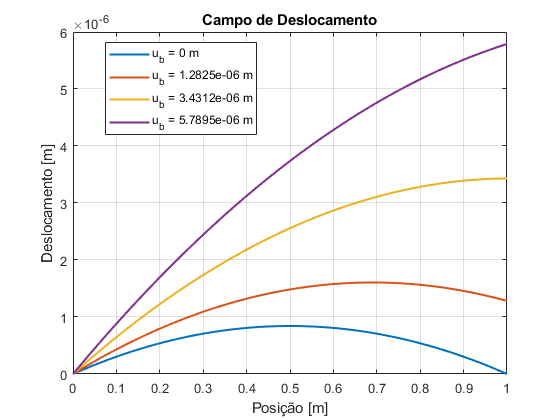

%% Parâmetros de entrada
L = 1.0;                                    % Comprimento da barra [m]
nx = 200;                                   % Número de pontos em x
x = linspace(0, L, nx);                     % Coordenadas x
h = L / (nx - 1);                           % Comprimento dos intervalos
A = pi * (0.015^2);                         % Área da seção [m^2]
E = 210e9;                                  % Módulo de Young [Pa]
q0 = 1e3;                                   % Carga distribuída máxima [N/m]
ua = 0;                                     % Deslocamento à esquerda [m]
ubs = [0, 1.2825e-6, 3.4312e-6, 5.7895e-6]; % Deslocamento à direita [m]

% Cria a figura e o subplot uma vez
figure;
subplot(1, 1, 1);

%% Iterar sobre os diferentes valores de ub e calcular uana para cada um
for i = 1:length(ubs)
    ub = ubs(i);

    % Obter a solução particular up e sua derivada
    up = (-q0 * x.^2) / (2 * E * A * L) + ...
         ((ub + (q0 * L) / (2 * E * A)) / L) * x;
    dup = (-q0 * x) / (E * A * L) + ...
          ((ub + (q0 * L) / (2 * E * A)) / L);

    % Obter os valores constantes para uh e sua derivada duh
    up0 = up(1);
    upL = up(end);
    c2 = ua - up0;
    c1 = (ub - upL - c2) / L;

    % Obter a solução analítica uana e sua derivada duana
    uana = up + c1 * x + c2;
    duana = dup + c1;

    % Plotar o deslocamento no mesmo gráfico
    plot(x, uana, 'LineWidth', 1.5, 'DisplayName', ['u_b = ', num2str(ub), ' m']);
    hold on;
end

%% Configurações finais do gráfico
title('Campo de Deslocamento');
grid on; hold off; xlabel('Posição [m]'); ylabel('Deslocamento [m]');
legend('Location', 'Best');

(2) Repita o item anterior para o caso de carga variando linearmente q(x) = q0x/L.

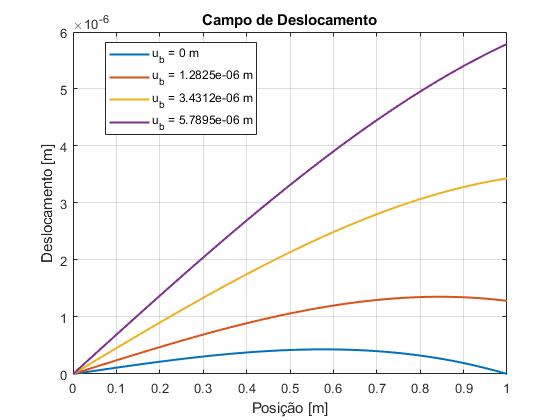

%% Parâmetros de entrada
L = 1.0;                                    % Comprimento da barra [m]
nx = 200;                                   % Número de pontos em x
x = linspace(0, L, nx);                     % Coordenadas x
h = L / (nx - 1);                           % Comprimento dos intervalos
A = pi * (0.015^2);                         % Área da seção [m^2]
E = 210e9;                                  % Módulo de Young [Pa]
q0 = 1e3;                                   % Carga distribuída máxima [N/m]
ua = 0;                                     % Deslocamento à esquerda [m]
ubs = [0, 1.2825e-6, 3.4312e-6, 5.7895e-6]; % Deslocamento à direita [m]

% Cria a figura e o subplot uma vez
figure;
subplot(1, 1, 1);

%% Iterar sobre os diferentes valores de ub e calcular uana para cada um
for i = 1:length(ubs)
    ub = ubs(i);

    % Obter a solução particular up e sua derivada
    up = (-q0 * x.^3) / (6 * E * A * L) + ...
         ((ub + (q0 * L^2) / (6 * E * A)) / L) * x;
    dup = -q0 * x.^2 / (2 * E * A * L) + ...
          (ub / L + q0 / (6 * E * A));

    % Obter os valores constantes para uh e sua derivada duh
    up0 = up(1);
    upL = up(end);
    c2 = ua - up0;
    c1 = (ub - upL - c2) / L;

    % Obter a solução analítica uana e sua derivada duana
    uana = up + c1 * x + c2;
    duana = dup + c1;

    % Plotar o deslocamento no mesmo gráfico
    plot(x, uana, 'LineWidth', 1.5, 'DisplayName', ['u_b = ', num2str(ub), ' m']);
    hold on;
end

% Configurações finais do gráfico
title('Campo de Deslocamento');
grid on; hold off; xlabel('Posição [m]'); ylabel('Deslocamento [m]');
legend('Location', 'Best');

(3) Usando o programa desenvolvido previamente em sala de aula, que resolve o problema da barra com carga constante pelo método dos Elementos Finitos, pede-se:

- Para a barra de seção constante compare as soluções numéricas com as analíticas para diferentes discretizações (nel = 5, 10, 20, 40). Faça um gráfico comparando as soluções analíticas e numéricas. Faça um gráfico dos erros em porcentagem calculados em cada ponto. Calcule e informe a norma euclidiana dos erros obtidos. Repita o procedimento para cada discretização adotada e faça uma análise de convergência usando a escala logarítmica. Comente e justifique os resultados.

Para a barra de seção constante e livre à direita:

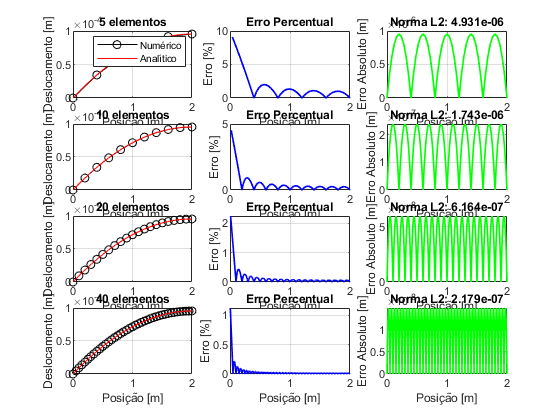

clc; clear all;

%% Parâmetros de entrada
L = 2;               % Comprimento total da Barra
E = 200e9;           % Módulo de elasticidade
A = pi * (0.01^2);   % Área da seção transversal
p0 = 3000;           % Carga distribuída constante

nels = [5, 10, 20, 40];
erro_euclidiano = zeros(1, length(nels));

%% Resolução
for nel_idx = 1:length(nels)
    % Parâmetros do Elemento
    nel = nels(nel_idx);
    nnos = nel + 1;
    h = L / nel;
    coord = linspace(0, L, nnos);
    inci = [(1:nnos-1)' (2:nnos)'];

    % Inicialização de Matrizes
    ke = ((E * A) / h) * [1 -1; -1 1];
    fe = (p0 * h / 2) * [1; 1];
    K = zeros(nnos, nnos);
    F = zeros(nnos, 1);
    u = zeros(nnos, 1);

    % Montagem de K e F
    for i = 1:nel
        no1 = inci(i, 1);
        no2 = inci(i, 2);
        loc = [no1, no2];
        K(loc, loc) = K(loc, loc) + ke;
        F(loc) = F(loc) + fe;
    end 

    % Condições de Contorno
    freedofs = 2:nnos;
    u(freedofs) = K(freedofs, freedofs) \ F(freedofs);

    % Solução Analítica
    x = linspace(0, L, 10 * nel + 1);
    ua = (p0 / (2 * E * A)) * (2 * L - x) .* x;

    % Interpolação da Solução Numérica
    u_interp = zeros(10 * nel + 1, 1);
    for i = 1:nel
        no1 = inci(i, 1);
        no2 = inci(i, 2);
        u1 = u(no1);
        u2 = u(no2);
        xx = linspace(h / 10, h - h / 10, 9);

        for j = 1:9
            N1 = (h - xx(j)) / h;
            N2 = xx(j) / h;
            u_interpele = N1 * u1 + N2 * u2;
            u_interp((no1 - 1) * 10 + j + 1) = u_interpele;
        end
        u_interp((no1 - 1) * 10 + 11) = u(no2);
    end

    % Cálculo dos Erros
    erro_absolut = abs(ua - u_interp');
    erro_percent = (erro_absolut ./ ua) * 100;
    erro_euclidiano(nel_idx) = norm(erro_absolut);
    titulo1 = sprintf('Norma L2: %.3e', erro_euclidiano(nel_idx));

    %% Plotagem dos Resultados
    % Comparação entre Solução Numérica e Analítica
    subplot(length(nels), 3, 3 * nel_idx - 2);
    plot(coord, u, 'o-k', x, ua, '-r'); 
    grid on;
    xlabel('Posição [m]'); ylabel('Deslocamento [m]');
    title(sprintf('%d elementos', nel));
    if nel_idx == 1
        legend('Numérico', 'Analítico');
    end

    % Gráfico de Erros Percentuais
    subplot(length(nels), 3, 3 * nel_idx - 1);
    plot(x, erro_percent, '-b', 'LineWidth', 1.25);
    title('Erro Percentual');
    xlabel('Posição [m]'); ylabel('Erro [%]');
    grid on;

    % Gráfico de Erros Absolutos
    subplot(length(nels), 3, 3 * nel_idx);
    plot(x, erro_absolut, '-g', 'LineWidth', 1.25);
    title(titulo1);
    xlabel('Posição [m]'); ylabel('Erro Absoluto [m]');
    grid on;
end

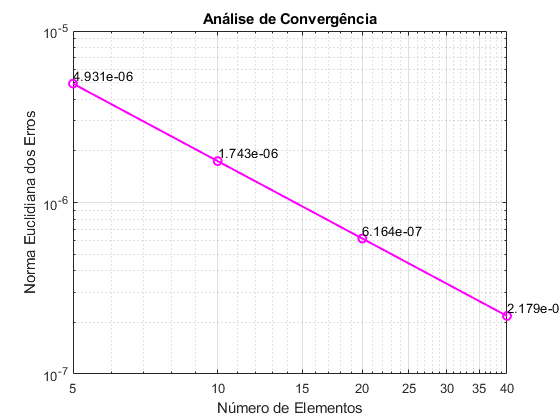


%% Análise de Convergência
figure;
loglog(nels, erro_euclidiano, 'o-m', 'LineWidth', 1.5);
xlabel('Número de Elementos'); ylabel('Norma Euclidiana dos Erros');
title('Análise de Convergência'); grid on;

% Exibir valores dos erros em cada ponto
for nel_idx = 1:length(nels)
    text(nels(nel_idx), erro_euclidiano(nel_idx), sprintf('%.3e', erro_euclidiano(nel_idx)), ...
        'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');
end

Para a barra de seção constante e com valor de ub = 1.2825e-4m prescrito:

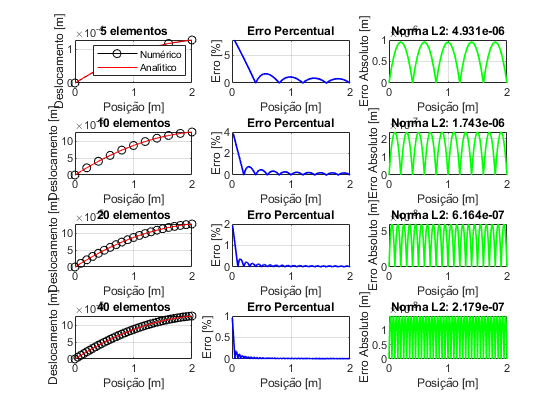

clc; clear all;

%% Parâmetros de entrada
L = 2;               % Comprimento total da Barra
E = 200e9;           % Módulo de elasticidade
A = pi * (0.01^2);   % Área da seção transversal
p0 = 3000;           % Carga distribuída constante
ub = 1.2825e-4;      % Deslocamento no extremo direito

nels = [5, 10, 20, 40];
erro_euclidiano = zeros(1, length(nels));

%% Resolução
for nel_idx = 1:length(nels)
    % Parâmetros do Elemento
    nel = nels(nel_idx);
    nnos = nel + 1;
    h = L / nel;
    coord = linspace(0, L, nnos);
    inci = [(1:nnos-1)' (2:nnos)'];

    % Inicialização de Matrizes
    ke = ((E * A) / h) * [1 -1; -1 1];
    fe = (p0 * h / 2) * [1; 1];
    K = zeros(nnos, nnos);
    F = zeros(nnos, 1);
    u = zeros(nnos, 1);

    % Montagem de K e F
    for i = 1:nel
        no1 = inci(i, 1);
        no2 = inci(i, 2);
        loc = [no1, no2];
        K(loc, loc) = K(loc, loc) + ke;
        F(loc) = F(loc) + fe;
    end 

    % Aplicação das Condições de Contorno
    K(1, :) = 0; K(end, :) = 0;
    K(1, 1) = 1; K(end, end) = 1;
    F(1) = 0; F(end) = ub;
    
    % Cálculo do Deslocamento
    u = K \ F;

    % Solução Analítica
    x = linspace(0, L, 10 * nel + 1);
    ua = (1 / (E * A)) * (-0.5 * p0 * x.^2 + ((ub * E * A + 0.5 * p0 * L^2) / L) * x);

    % Interpolação da Solução Numérica
    u_interp = zeros(10 * nel + 1, 1);
    for i = 1:nel
        no1 = inci(i, 1);
        no2 = inci(i, 2);
        u1 = u(no1);
        u2 = u(no2);
        xx = linspace(h / 10, h - h / 10, 9);

        for j = 1:9
            N1 = (h - xx(j)) / h;
            N2 = xx(j) / h;
            u_interpele = N1 * u1 + N2 * u2;
            u_interp((no1 - 1) * 10 + j + 1) = u_interpele;
        end
        u_interp((no1 - 1) * 10 + 11) = u(no2);
    end

    % Cálculo dos Erros
    erro_absolut = abs(ua - u_interp');
    erro_percent = (erro_absolut ./ ua) * 100;
    erro_euclidiano(nel_idx) = norm(erro_absolut);
    titulo1 = sprintf('Norma L2: %.3e', erro_euclidiano(nel_idx));

    %% Plotagem dos Resultados
    % Comparação entre Solução Numérica e Analítica
    subplot(length(nels), 3, 3 * nel_idx - 2);
    plot(coord, u, 'o-k', x, ua, '-r'); 
    grid on;
    xlabel('Posição [m]'); ylabel('Deslocamento [m]');
    title(sprintf('%d elementos', nel));
    if nel_idx == 1
        legend('Numérico', 'Analítico');
    end

    % Gráfico de Erros Percentuais
    subplot(length(nels), 3, 3 * nel_idx - 1);
    plot(x, erro_percent, '-b', 'LineWidth', 1.25);
    title('Erro Percentual');
    xlabel('Posição [m]'); ylabel('Erro [%]');
    grid on;

    % Gráfico de Erros Absolutos
    subplot(length(nels), 3, 3 * nel_idx);
    plot(x, erro_absolut, '-g', 'LineWidth', 1.25);
    title(titulo1);
    xlabel('Posição [m]'); ylabel('Erro Absoluto [m]');
    grid on;
end


%% Análise de Convergência
figure;
loglog(nels, erro_euclidiano, 'o-m', 'LineWidth', 1.5);
xlabel('Número de Elementos'); ylabel('Norma Euclidiana dos Erros');
title('Análise de Convergência'); grid on;

% Exibir valores dos erros em cada ponto
for nel_idx = 1:length(nels)
    text(nels(nel_idx), erro_euclidiano(nel_idx), sprintf('%.3e', erro_euclidiano(nel_idx)), ...
        'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');
end
hold off;

- Repita o item anterior para a barra com carga distribuída linear.

Para a barra com carga distribuída linear e livre à direita:

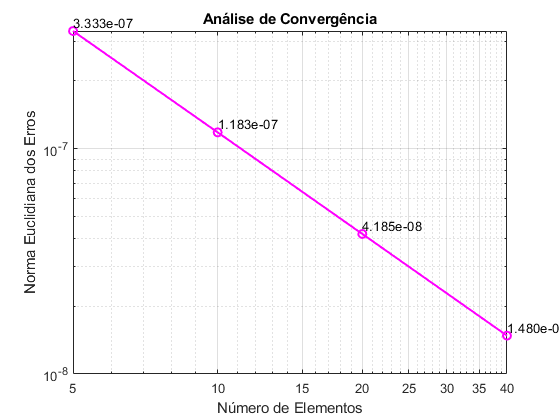

clc; clear all;

%% Parâmetros de entrada
E = 68e9;                  % Módulo de elasticidade (Pa)
A = pi * (0.05^2);         % Área da seção transversal (m²)
L = 2.0;                   % Comprimento da barra (m)
p0 = 3000;                 % Carga máxima distribuída (N/m)

nels = [5, 10, 20, 40];    % Número de elementos a serem analisados
erro_euclidiano = zeros(1, length(nels));

%% Resolução para cada número de elementos
for nel_idx = 1:length(nels)
    nel = nels(nel_idx);   % Número de elementos
    nnos = nel + 1;        % Número de nós
    h = L / nel;           % Comprimento de cada elemento
    coord = linspace(0, L, nnos); % Coordenadas dos nós
    inci = [(1:nnos-1)' (2:nnos)']; % Matriz de conectividade

    % Inicialização de Matrizes Globais
    ke = ((E * A) / h) * [1 -1; -1 1];         % Matriz de rigidez do elemento
    fe = (p0 * h / 2) * [1; 1];                % Vetor de forças do elemento
    K = zeros(nnos, nnos);                     % Matriz de rigidez global
    F = zeros(nnos, 1);                        % Vetor de forças global
    u = zeros(nnos, 1);                        % Vetor de deslocamentos

    % Montagem da Matriz de Rigidez e Vetor de Forças Globais
    for i = 1:nel
        no1 = inci(i, 1);
        no2 = inci(i, 2);
        loc = [no1, no2];
        K(loc, loc) = K(loc, loc) + ke;

        % Cálculo das Forças Nodais Equivalentes para Carga Triangular
        x1 = coord(no1);
        x2 = coord(no2);
        f1 = p0 * (x1 / L);
        f2 = p0 * (x2 / L);
        
        % Força nodal exata via integração da carga distribuída
        fe = (h / 6) * [2*f1 + f2; f1 + 2*f2];
        F(no1) = F(no1) + fe(1); 
        F(no2) = F(no2) + fe(2);
    end

    % Aplicação das Condições de Contorno
    freedofs = 2:nnos;  % Graus de liberdade livres
    u(freedofs) = K(freedofs, freedofs) \ F(freedofs);

    % Solução Analítica
    x = linspace(0, L, 10 * nel + 1);
    ua = (p0 / (6 * E * A * L)) * x .* (3 * L^2 - x.^2);

    %% Interpolação da Solução Numérica
    u_interp = zeros(10 * nel + 1, 1);
    for i = 1:nel
        no1 = inci(i, 1);
        no2 = inci(i, 2);
        u1 = u(no1);
        u2 = u(no2);

        % Gera pontos internos igualmente espaçados no elemento
        xx = linspace(h / 10, h - h / 10, 9);

        for j = 1:9
            N1 = (h - xx(j)) / h;
            N2 = xx(j) / h;
            u_interp((no1 - 1) * 10 + j + 1) = N1 * u1 + N2 * u2;
        end
        u_interp((no1 - 1) * 10 + 11) = u(no2);
    end

    %% Cálculo dos Erros
    erro_absolut = abs(ua - u_interp.');
    erro_percent = (erro_absolut ./ ua) * 100;
    erro_euclidiano(nel_idx) = norm(erro_absolut);
    titulo1 = sprintf('Norma L2: %.3e', erro_euclidiano(nel_idx));
    
    %% Plotagem dos Resultados para cada nel
    % Solução Numérica e Analítica
    subplot(length(nels), 3, 3 * nel_idx - 2);
    plot(coord, u, 'o-k', x, ua, '-r'); 
    grid on;
    xlabel('Posição [m]'); ylabel('Deslocamento [m]');
    title(sprintf('%d elementos', nel));
    if nel_idx == 1
        legend('Numérico', 'Analítico');
    end

    % Erros Percentuais
    subplot(length(nels), 3, 3 * nel_idx - 1);
    plot(x, erro_percent, '-b', 'LineWidth', 1.25);
    title('Erro Percentual');
    xlabel('Posição [m]'); ylabel('Erro [%]');
    grid on;

    % Erros Absolutos
    subplot(length(nels), 3, 3 * nel_idx);
    plot(x, erro_absolut, '-g', 'LineWidth', 1.25);
    title(titulo1);
    xlabel('Posição [m]'); ylabel('Erro Absoluto [m]');
    grid on;
end

%% Análise de Convergência
figure;
loglog(nels, erro_euclidiano, 'o-m', 'LineWidth', 1.5);
xlabel('Número de Elementos'); ylabel('Norma Euclidiana dos Erros');
title('Análise de Convergência'); grid on;

% Adicionar valores dos erros nas bolinhas
for nel_idx = 1:length(nels)
    text(nels(nel_idx), erro_euclidiano(nel_idx), ...
        sprintf('%.3e', erro_euclidiano(nel_idx)), ...
        'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');
end
hold off;

Para a barra com carga distribuída linear e com valor de ub = 3.4312e-6m prescrito:

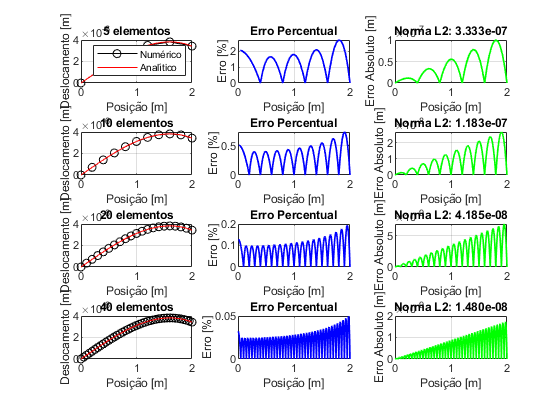

clc; clear all;

%% Parâmetros de entrada
E = 68e9;                  % Módulo de elasticidade (Pa)
A = pi * (0.05^2);         % Área da seção transversal (m²)
L = 2.0;                   % Comprimento da barra (m)
p0 = 3000;                 % Carga máxima distribuída (N/m)

nels = [5, 10, 20, 40];  % Número de elementos para análise
ub = 3.4312e-6;          % Deslocamento na extremidade da barra
erro_euclidiano = zeros(1, length(nels));  % Erro euclidiano

%% Resolução para cada valor de nels
for nel_idx = 1:length(nels)
    nel = nels(nel_idx);      % Número de elementos
    nnos = nel + 1;           % Número de nós
    h = L / nel;              % Comprimento de cada elemento
    coord = [0:h:L];          % Coordenadas dos nós
    inci = [(1:nnos-1)' (2:nnos)'];  % Matriz de conectividade

    % Inicialização das matrizes
    ke = ((E*A) / h) * [1 -1; -1 1];  % Matriz de rigidez do elemento
    fe = (p0 * h / 2) * [1; 1];       % Vetor de forças do elemento
    K = zeros(nnos, nnos);            % Matriz de rigidez global
    F = zeros(nnos, 1);               % Vetor de forças global
    u = zeros(nnos, 1);               % Vetor de deslocamentos

    % Montagem da Matriz de Rigidez Global e do Vetor de Forças
    for i = 1:nel
        no1 = inci(i, 1);
        no2 = inci(i, 2);
        loc = [no1 no2];
        K(loc, loc) = K(loc, loc) + ke;

        % Cálculo das forças nodais equivalentes para carga distribuída triangular
        x1 = coord(no1);
        x2 = coord(no2);
        f1 = p0 * x1 / L;
        f2 = p0 * x2 / L;
        fe = (h / 6) * [f1 + 2*f2; 2*f1 + f2];
        F(no1) = F(no1) + fe(1);
        F(no2) = F(no2) + fe(2);
    end

    % Aplicação das Condições de Contorno
    K(1, :) = 0; K(end, :) = 0;       % Condição de rigidez nula nas extremidades
    K(1, 1) = 1; K(end, end) = 1;     % Condição de rigidez unitária nas extremidades
    F(1) = 0; F(end) = ub;            % Condição de deslocamento na extremidade

    % Resolução do sistema de equações para encontrar os deslocamentos
    u = K \ F;

    %% Solução Analítica
    x = linspace(0, L, 10 * nel + 1);
    ua = (-p0 * x.^3) / (6 * E * A * L) + ((ub + (p0 * L^2) / (6 * E * A)) / L) * x;

    %% Interpolação da Solução Numérica
    u_interp = zeros(10 * nel + 1, 1);  % Vetor para armazenar os deslocamentos interpolados

    % Loop sobre cada elemento para interpolar a solução
    for i = 1:nel
        no1 = inci(i, 1);
        no2 = inci(i, 2);
        u1 = u(no1);  % Deslocamento no nó 1
        u2 = u(no2);  % Deslocamento no nó 2

        % Gera pontos internos igualmente espaçados no elemento
        xx = linspace(h / 10, h - h / 10, 9);

        for j = 1:9
            % Funções de forma
            N1 = (h - xx(j)) / h;
            N2 = xx(j) / h;

            % Interpolação dos deslocamentos para os pontos internos
            u_interpele = N1 * u1 + N2 * u2;
            u_interp((no1 - 1) * 10 + j + 1) = u_interpele;
        end
        u_interp((no1 - 1) * 10 + 11) = u(no2);
    end

    %% Cálculo dos Erros
    erro_absolut = abs(ua - u_interp.');
    erro_percent = (erro_absolut ./ ua) * 100;  % Erro percentual
    erro_euclidiano(nel_idx) = norm(erro_absolut);  % Norma euclidiana dos erros
    titulo1 = sprintf('Norma L2: %.3e', erro_euclidiano(nel_idx));

    %% Plotagem dos Resultados
    % Plotar a solução numérica e analítica
    subplot(length(nels), 3, 3 * nel_idx - 2);
    plot(coord, u, 'o-k', x, ua, '-r'); 
    grid on;
    xlabel('Posição [m]'); ylabel('Deslocamento [m]');
    title(sprintf('%d elementos', nel));
    if nel_idx == 1
        legend('Numérico', 'Analítico');
    end

    % Plotar o erro percentual
    subplot(length(nels), 3, 3 * nel_idx - 1);
    plot(x, erro_percent, '-b', 'LineWidth', 1.25);
    title('Erro Percentual');
    xlabel('Posição [m]'); ylabel('Erro [%]');
    grid on;

    % Plotar o erro absoluto
    subplot(length(nels), 3, 3 * nel_idx);
    plot(x, erro_absolut, '-g', 'LineWidth', 1.25);
    grid on;
    title(titulo1);
    xlabel('Posição [m]'); ylabel('Erro Absoluto [m]');
end


%% Análise de Convergência
figure;
loglog(nels, erro_euclidiano, 'o-m', 'LineWidth', 1.5);
xlabel('Número de Elementos'); ylabel('Norma Euclidiana dos Erros');
title('Análise de Convergência'); grid on;

% Adicionar valores dos erros nas bolinhas
for nel_idx = 1:length(nels)
    text(nels(nel_idx), erro_euclidiano(nel_idx), ...
        sprintf('%.3e', erro_euclidiano(nel_idx)), ...
        'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');
end
hold off;

#### **EXERCÍCIO III - Barra de Seção Constante com Carga Variável**

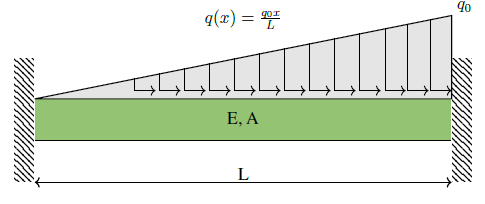

Se E, A, L são constantes, com as condições de contorno dadas por u(0) = 0 e u(L) = 0, então a solução analítica deste problema é dada por:

Para este caso pede-se:

(1) A barra é feita de aço com E = 210GPa, com seção circular de diâmetro 30 mm e a carga linear com q0 = 1kN/m e L = 10m. Calcule e faça um gráfico da solução analítica em deslocamento e em tensão. Lembrando que neste caso a tensão pode ser calculada por σxx = Nx(x)/A.

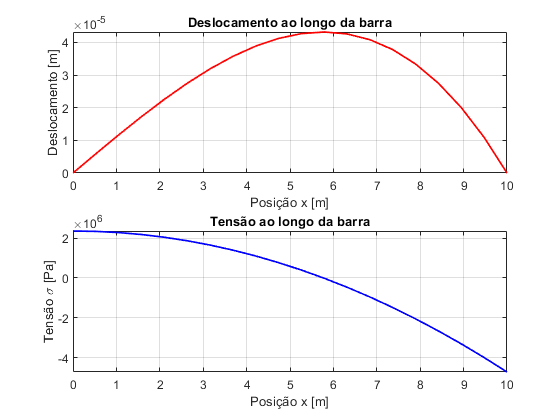

close all; clear all;

%% Parâmetros de entrada
L = 10;                  % Comprimento da barra [m]
nx = 20;                 % Número de pontos em x
x = linspace(0, L, nx)'; % Coordenadas x
E = 210e9;               % Módulo de elasticidade [Pa]
A = pi * (0.015^2);      % Área da seção transversal [m^2]
Po = 1e3;                % Força aplicada [N]

%% Cálculo do deslocamento y
y = Po / (6 * E * A * L) * (L.^2 * x - x.^3);

%% Cálculo da tensão sigma
dudx = Po * (L.^2 - 3 * x.^2) / (6 * E * A * L);
Nx = E * A * dudx;
sigma = Nx / A;

%% Subplot 1: Deslocamento
figure;
subplot(2, 1, 1);
plot(x, y, '-r', 'LineWidth', 1.25);
title('Deslocamento ao longo da barra'); grid on;
xlabel('Posição x [m]'); ylabel('Deslocamento [m]');

%% Subplot 2: Tensão
subplot(2, 1, 2);
plot(x, sigma, '-b', 'LineWidth', 1.25);
title('Tensão ao longo da barra'); grid on;
xlabel('Posição x [m]'); ylabel('Tensão \sigma [Pa]');

(2) Usando a análise matricial de estruturas, desenvolva um código para o caso de carga variando linearmente. Compare as soluções numéricas obtidas com as analíticas para diferentes discretizações (5, 10, 20 e 40 elementos). Faça um gráfico comparando as soluções analíticas e numéricas em deslocamentos e em tensão. Faça um gráfico dos erros em porcentagem calculados em cada nó. Calcule e informe a norma euclidiana dos erros obtidos. Repita o procedimento para cada discretização adotada. Comente os resultados.

clc; clear all;

%% Parâmetros de entrada
E = 210e9;           % Módulo de elasticidade do material (Pa)
A = pi * (0.015^2);  % Área da seção transversal da barra (m²)
L = 10.0;            % Comprimento da barra (m)
p0 = 1e3;            % Carga máxima distribuída ao longo da barra (N/m)
nels = [5, 10, 20, 40];  % Número de elementos a serem considerados

%% Resolução
for nel_idx = 1:length(nels)
    nel = nels(nel_idx);
    nnos = nel + 1;   % Número de nós
    h = L / nel;      % Comprimento de cada elemento
    coord = 0:h:L;    % Coordenadas dos nós
    inci = [[1:nnos-1]' [2:nnos]'];   % Conectividade dos elementos

    % Inicialização das matrizes de rigidez e forças
    Kg = zeros(nnos, nnos);  % Matriz global de rigidez
    Fg = zeros(nnos, 1);     % Vetor global de forças
    ke = ((E * A) / h) * [1 -1; -1 1];  % Matriz de rigidez local do elemento

    % Montagem da matriz de rigidez e do vetor de forças globais
    for i = 1:nel
        fe = ((((p0 / L) * coord(i) * h) / 2) * [1; 1]) + (((((p0 / L) * coord(i+1)) - ((p0 / L) * coord(i))) * h) / 2 / 3) * [1; 2];
        no1 = inci(i, 1);
        no2 = inci(i, 2);
        loc = [no1 no2];
        Kg(loc, loc) = Kg(loc, loc) + ke;
        Fg(loc, 1) = Fg(loc, 1) + fe;
    end 

    % Condições de contorno
    fixed_dofs = [1, nnos];
    free_dofs = setdiff(1:nnos, fixed_dofs);

    % Resolver o sistema para os graus de liberdade livres
    u = zeros(nnos, 1);
    u(free_dofs) = Kg(free_dofs, free_dofs) \ Fg(free_dofs);

    FR = Kg * u;
    T = zeros(nel, 1);

    % Calcular as coordenadas dos pontos médios de cada elemento
    coord_mid = (coord(1:end-1) + coord(2:end)) / 2;

    % Calculo das tensões dentro de cada elemento
    somaF = 0;
    for j = 1:(nnos-1)
        somaF = somaF + FR(j);
        FIE = -somaF;
        te = FIE / A;
        T(j, 1) = T(j, 1) + te; 
    end

    %% Solução analítica para carga triangular 
    x = [0:h/10:L];
    ua = (1/(E*A)) * ((-p0 * x.^3) / (6 * L) + (p0 * L * x) / 6);
    sxx = ((-p0 * x.^2) / (2 * L) + (p0 * L) / 6) / A;

    %% Erros: Deslocamentos e Tensões
    % Interpolação dos resultados numéricos
    u_interp = zeros((nnos * 10) - 10, 1);
    t_interp = zeros((nnos * 10) - 10, 1);

    for i = 1:nel
        no1 = inci(i, 1);
        no2 = inci(i, 2);

        u1 = u(no1);
        u2 = u(no2);

        % Gera pontos internos igualmente espaçados no elemento
        xx = linspace(h / 10, h - (h / 10), 9);

        for j = 1:9
            % Tensão e deformação dentro do elemento
            t_interpele = T(i);
            t_interp(((no1 - 1) * 10) + (1 + j)) = t_interpele;
            t_interp((no2 * 10) - 9) = t_interpele;

            % Funções de forma para o deslocamento
            N1 = (h - xx(j)) / h;
            N2 = xx(j) / h;

            % Interpolação dos deslocamentos para os pontos internos
            u_interpele = N1 * u1 + N2 * u2;
            u_interp(((no1 - 1) * 10) + (1 + j)) = u_interpele;
        end
        u_interp(((no1 - 1) * 10) + 11) = u(no2);
    end

    % Cálculo dos erros absolutos e relativos
    erro_absolut = abs(ua - u_interp');
    erro_absolut2 = abs(sxx - t_interp');
    erro_percent = (erro_absolut ./ ua) * 100;
    erro_percent2 = (erro_absolut2 ./ sxx) * 100;

    % Cálculo da norma euclidiana dos erros
    erro_euclidiano1 = norm(erro_absolut);
    erro_euclidiano2 = norm(erro_absolut2);
    titulo1 = sprintf('Norma L2 (Deslocamentos): %.4e', erro_euclidiano1);
    titulo2 = sprintf('Norma L2 (Tensões): %.4e', erro_euclidiano2);

    %% Plotagem
    % Plotagem dos resultados de deslocamentos
    figure(1);
    subplot(length(nels), 3, 3 * nel_idx - 2);
    plot(coord, u, 'o-k', 'DisplayName', 'Numérico'); hold on;
    plot(x, ua, '-r', 'DisplayName', 'Analítico');
    xlabel('Posição [m]'); ylabel('Deslocamento [m]');
    title(sprintf('(%d elementos)', nel)); grid on;
    if nel_idx == 1
        legend('show');
    end

    subplot(length(nels), 3, 3 * nel_idx - 1);
    plot(x, erro_percent, '-b', 'LineWidth', 1.25); 
    title('Erro Percentual'); grid on;
    xlabel('Posição x [m]'); ylabel('Erro [%]'); hold on;

    subplot(length(nels), 3, 3 * nel_idx);
    plot(x, erro_absolut, '-g', 'LineWidth', 1.25); 
    title(titulo1); grid on;
    xlabel('Posição x [m]'); ylabel('Erro Absoluto [m]');
    hold on   

    % Plotagem dos resultados de tensões
    figure(2);
    subplot(length(nels), 3, 3 * nel_idx - 2);
    bar((coord(1:end-1) + coord(2:end)) / 2, T, 'FaceColor', 'k'); 
    hold on; plot(x, sxx, '-b'); 
    xlabel('Posição [m]'); ylabel('Tensão [Pa]');
    title(sprintf('(%d elementos)', nel)); grid on;
    if nel_idx == 1
        legend('Numérico', 'Analítico');
    end

    subplot(length(nels), 3, 3 * nel_idx - 1);
    plot(x, erro_percent2, '-b', 'LineWidth', 1.25); 
    title('Erro Percentual'); grid on;
    xlabel('Posição x [m]'); ylabel('Erro [%]');
    hold on;

    subplot(length(nels), 3, 3 * nel_idx);
    plot(x, erro_absolut2, '-g', 'LineWidth', 1.25);
    title(titulo2); grid on;
    xlabel('Posição x [m]'); ylabel('Erro Absoluto [Pa]');
    hold off;
end

#### **EXERCÍCIO IV - Barra de Seção Variável com Condição de Neumann**

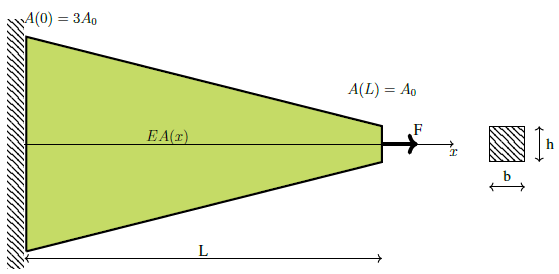

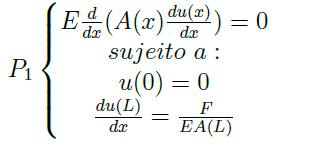

Para este caso pede-se:

(1) Encontre a solução analítica do problema P1.

(2) A barra é feita de aço com E = 210GP a, com seção retangular com b = 30mm e h = 40mm para o ponto x = L, o comprimento é L = 10m. Faça um gráfico da solução analítica em deslocamento e em tensão. Lembrando que neste caso a tensão pode ser calculada por σxx = Nx(x)/A.

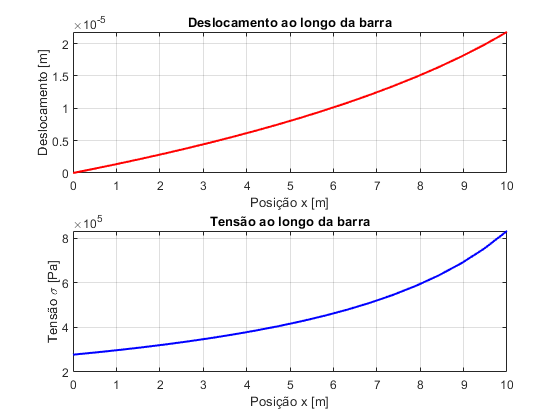

close all; clear all;

%% Parâmetros de entrada
L = 10;                  % Comprimento da barra [m]
nx = 20;                 % Número de pontos x
x = linspace(0, L, nx)'; % Coordenadas x
E = 210e9;               % Módulo de elasticidade [Pa]
b = 0.03;                % Largura da seção [m]
h = 0.04;                % Altura da seção [m]
A = b * h;               % Área da seção transversal [m^2]
F = 1000;                % Força aplicada [N]

%% Cálculo do deslocamento y
y = -(F * L / (2 * E * A)) * log(1 - (2 * x / (3 * L)));

%% Cálculo da tensão sigma
dudx = (F * L) ./ (A * E * (3 * L - 2 * x));
Nx = E * A * dudx;
sigma =  Nx / A;

%% Subplot 1: Deslocamento
figure;
subplot(2, 1, 1);
plot(x, y, '-r', 'LineWidth', 1.5);
title('Deslocamento ao longo da barra');
xlabel('Posição x [m]');
ylabel('Deslocamento [m]');
grid on;

%% Subplot 2: Tensão
subplot(2, 1, 2);
plot(x, sigma, '-b', 'LineWidth', 1.5);
title('Tensão ao longo da barra');
xlabel('Posição x [m]');
ylabel('Tensão \sigma [Pa]');
grid on;

(3) Desenvolva um código usando a análise matricial de estruturas e considerando a área variando linearmente, com a condição de Neumann em x = L. Compare as soluções numéricas obtidas com as analíticas para diferentes discretizações (5, 10, 20 e 40 elementos). Faça um gráfico comparando as soluções analíticas e numéricas em deslocamentos e em tensão. Faça um gráfico dos erros em porcentagem calculados em cada nó da malha. Calcule e informe a norma euclidiana dos erros obtidos. Repita o procedimento para cada discretização adotada. Comente os resultados.

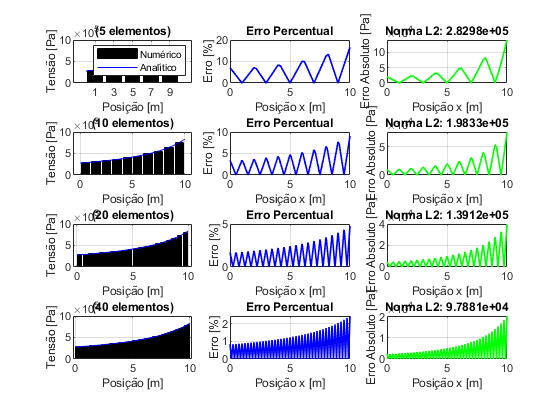

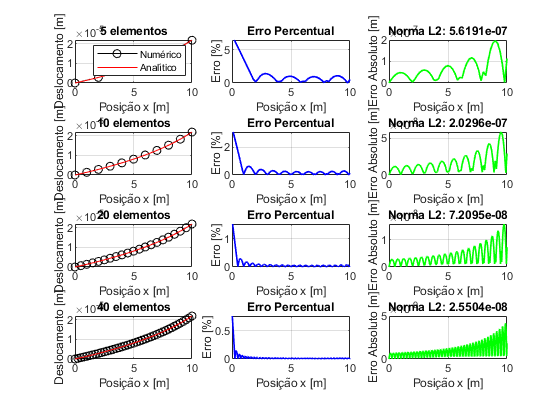

clc; clear all;

%% Parâmetros de entrada
E = 210e9;      % Módulo de elasticidade (Pa)
A0 = 0.03*0.04; % Área na seção transversal no ponto x = 0 (m²)
AI = 3*A0;      % Área na seção transversal no ponto x = L (m²)
P0 = 0;         % Carga distribuída
L = 10;         % Comprimento total da barra (m)
F = 1000;       % Carga pontual na extremidade direita (N)
nels = [5, 10, 20, 40];

%% Resolução
for n_idx = 1:length(nels)
    nel = nels(n_idx);
    nnos = nel + 1;
    h = L / nel;
    coord = [0:h:L];
    inci = [[1:nnos-1]' [2:nnos]'];

    Kg = zeros(nnos, nnos);
    Fg = zeros(nnos, 1);

    % Montagem da matriz de rigidez global
    for e = 1:nel
        % Coordenadas do elemento
        x1 = coord(inci(e, 1));
        x2 = coord(inci(e, 2));

        % Áreas nos pontos x1 e x2 (variação linear)
        A1 = A0 * (3 - (2 * x1 / L));
        A2 = A0 * (3 - (2 * x2 / L));

        % Rigidez do elemento
        ke = (E / (x2 - x1)) * [(A1 + A2) / 2, -(A1 + A2) / 2; -(A1 + A2) / 2, (A1 + A2) / 2];

        % Montagem na matriz global
        Kg(inci(e,:), inci(e,:)) = Kg(inci(e,:), inci(e,:)) + ke;
    end

    % Condições de contorno
    Fg(nnos) = Fg(nnos) + F;
    freedofs = [2:nnos];

    % Resolvendo o sistema de equações para deslocamento
    u = zeros(nnos, 1);
    u(freedofs,1) = Kg(freedofs,freedofs) \ Fg(freedofs,1);

    % Resolvendo o sistema de equações para tensões
    FR = Kg*u;
    T = zeros(nel, 1);

    % Pré-alocar o vetor coord_mid para os pontos médios de cada elemento
    coord_mid = zeros(1, nel);

    % Calcular as coordenadas dos pontos médios
    for i = 1:(nel)
        coord_mid(i) = (coord(i) + ((coord(i+1)- coord(i)) / 2));
    end

    % Calculo das tensões dentro de cada elemento
    somaF = 0;
    for j = 1:(nnos-1)
        Am = ((((-0.2)*A0*coord(j)) + AI) + (((-0.2)*A0*coord(j+1)) + AI)) / 2;
        somaF = somaF + FR(j);
        FIE = -somaF;
        TE = (FIE/Am);
        T(j,1) = T(j,1) + TE; 
    end

    % Solução analítica 
    x = [0:h/10:L];
    ua = ((-F*L)/(2*A0*E))*log(1 - (2*x / (3*L)));
    sxx = (F / (3 * A0)) ./ (1 - (2 * x / (3 * L)));

    %% ERROS 
    % ERROS DO DESLOCAMENTO INTERPOLANDO PELAS FUNÇÕES DE FORMA DO ELEMENTO
    % Interpolar a solução numérica para 10 pontos dentro de cada elemento
    u_interp = zeros((nnos*10)-10,1);
    t_interp = zeros((nnos*10)-10,1);

    % Loop sobre cada elemento
    for i = 1:nel
        no1 = inci (i,1);
        no2 = inci (i,2);

        % Deslocamentos nos nós do elemento
        u1 = u(no1);
        u2 = u(no2);

        % Gera pontos internos igualmente espaçados no elemento
        xx = linspace(h/10, h-(h/10), 9);

        for j = 1:9

        %Tensão e deformação dentro do elemento
        t_interpele = T(i);
        t_interp (((no1-1)*10)+(1+j)) =  t_interpele;
        t_interp ((no2*10)-9) =  t_interpele;
        t_interp(1) =  T(1);

        % Funções de forma para o deslocamento
        N1 = ((h) - xx(j)) / h;
        N2 = xx(j) / h;

        % Interpolação dos deslocamentos para os pontos internos
        u_interpele = N1 * u1 + N2 * u2;
        u_interp (((no1-1)*10)+(1+j)) =  u_interpele;
        end
        
        u_interp (((no1-1)*10)+11) =  u(no2);
    end

    % Calcular o erro absoluto nos pontos de interpolação
    erro_absolut = abs(ua - u_interp');
    erro_absolut2 = abs(sxx - t_interp');

    % Calcular o erro relativo em porcentagem nos pontos de interpolação
    erro_percent = (erro_absolut ./ ua) * 100;
    erro_percent2 = (erro_absolut2 ./ sxx) * 100;

    % Cálculo da norma euclidiana dos erros
    erro_euclidiano1 = norm(erro_absolut);
    titulo1 = sprintf('Norma L2: %.4e', erro_euclidiano1);
    erro_euclidiano2 = norm(erro_absolut2);
    titulo2 = sprintf('Norma L2: %.4e', erro_euclidiano2);

    %% Plotagem 
    figure(1);
    subplot(length(nels), 3, 3*n_idx-2);
    plot(coord, u, 'o-k', x, ua, '-R');
    grid on; xlabel('Posição x [m]'); ylabel('Deslocamento [m]');
    title(sprintf('%d elementos', nel));
    if n_idx == 1
        legend('Numérico', 'Analítico');
    end

    % Erro percentual no deslocamento
    subplot(length(nels), 3, 3*n_idx-1);
    plot(x, erro_percent, '-b', 'LineWidth', 1.25); 
    grid on; xlabel('Posição x [m]'); ylabel('Erro [%]');
    title('Erro Percentual'); hold on;

    % Erro absoluto com norma L2 no deslocamento
    subplot(length(nels), 3, 3*n_idx);
    plot(x, erro_absolut, '-g', 'LineWidth', 1.25); 
    title (titulo1); grid on;
    xlabel('Posição x [m]'); ylabel('Erro Absoluto [m]'); hold on;

    % Plotagem 
    figure(2);
    subplot(length(nels), 3, 3*n_idx-2);
    bar((coord(1:end-1) + coord(2:end)) / 2, T, 'FaceColor', 'k'); hold on;
    plot(x, sxx, '-b'); grid on;
    xlabel('Posição [m]'); ylabel('Tensão [Pa]');
    title(sprintf('(%d elementos)', nel));
    if n_idx == 1
        legend('Numérico', 'Analítico');
    end

    % Erro percentual na tensão
    subplot(length(nels), 3, 3*n_idx-1);
    plot(x, erro_percent2, '-b', 'LineWidth', 1.25); 
    grid on; xlabel('Posição x [m]'); ylabel('Erro [%]');
    title('Erro Percentual'); hold on;

    % Erro absoluto com norma L2 na tensão
    subplot(length(nels), 3, 3*n_idx);
    plot(x, erro_absolut2, '-g', 'LineWidth', 1.25); 
    title (titulo2); grid on;
    xlabel('Posição x [m]'); ylabel('Erro Absoluto [Pa]');
    hold off;
 end